## Data

% 
clear all; close all; clc;
set_env;
%

% Data --------------------------------------------------------------
% Constants
eps_0 = 8.85e-12; 			% F/m , permittivity of vacuum

% Geometry
% tp_0 = 25e-6; 				% m   , initial thickness of polymer layer
% l_0 = 50e-3 / 2; 			% m   , initial length of polymer layer

% Kapton
% epsilon_p = 4.5 * eps_0;	% F/m 		, permittivity of poymeric layer
% EBD_p = 70e6; 			    % V / m     , Breakdown field
% nu = 0.3; 				%  -        , Poisson's ratio of polymer
% Y_p = 4.5e5               % Pa        , Young's modulus
epsilon1_max = 0.1;

% Fluid 
% epsilon_f = 80 * eps_0; 		% F/m , permittivity of fluid (seawater)
% EBD_f = 30e3 / 0.5e-3                       % V / m   , Breakdown field

% Operational limits -------------------------------------------------
% VBD = EBD_f * [h_f + epsilon_f / epsilon_p * (x - h_f)];
% h_f is the "thickness" of the fluid layer	 where the term in [] is minimum

% epsilon_i = lambda_DE - 1; 	% - , Max strain


% Symbolic variables ------------------------------------------------
% Physical properties
syms nu Y_p epsilon_p epsilon_f EBD_p EBD_f real positive

% Geometry of the capacitor
syms x l_0 w tp_0 xi xi_0 tf_0 dt_f dttf real positive
% t_f(x) armature distance at a certain xsi

% Physical quantities
syms Uel(x) V F(x,V) C(x)
% 
% % Strains: eps1 along the polymer, eps3 thickness strain of the polymer
syms epsilon_1(x) epsilon_3(x)


## Equations

% Equations ---------------------------------------------------------
% epsilon_1(x) = sqrt(1 + x^2 / (4 * l_0^2)) - 1
% epsilon_3(x) = epsilon_1(x) * nu / (nu - 1)

% Stresses
sigma_1(x) = - Y_p * epsilon_1(x) / (nu^2 - 1)

$$sigma\_1(x) = -\frac{Y_{p}\,\epsilon_{1}\left(x\right)}{\nu^{2}-1}$$

sigma_2(x) = - Y_p * epsilon_1(x) * nu / (nu^2 - 1)

$$sigma\_2(x) = -\frac{Y_{p}\,\nu \,\epsilon_{1}\left(x\right)}{\nu^{2}-1}$$


% Geometry ------------------------------
l(x) = l_0 * (1 + epsilon_1(x));
t_p(x) = tp_0 * (1 + epsilon_3(x));

dt_f(x) = simplify(solve((x/2 - t_p) / l_0 == ((tf_0 + dttf) / 2) / (l_0 - (xi - xi_0)), dttf))

$$dt\_f(x) = -\left(\frac{{\mathrm{tf}}_{0}}{2\,\left(l_{0}-\xi +\xi_{0}\right)}-\frac{\frac{x}{2}-{\mathrm{tp}}_{0}\,\left(\epsilon_{3}\left(x\right)+1\right)}{l_{0}}\right)\,\left(2\,l_{0}-2\,\xi +2\,\xi_{0}\right)$$

t_f(x) = tf_0 + dt_f; 
A = l * w;
dA = w * (1 + epsilon_1(x)) ; % * dxsi

% Range limit
x_max = rhs(isolate(sstrain(epsilon_1(x)) == epsilon1_max, x))

$$x\_max = \frac{\sqrt{21}\,l_{0}}{5}$$


% Polymer infinitesimal capacitance
dCp = dA * epsilon_p / t_p

$$dCp(x) = \frac{\epsilon_{p}\,w\,\left(\epsilon_{1}\left(x\right)+1\right)}{{\mathrm{tp}}_{0}\,\left(\epsilon_{3}\left(x\right)+1\right)}$$

% Fluid infinitesimal capacitance
dCf = dA * epsilon_f / t_f

$$dCf(x) = \frac{\epsilon_{f}\,w\,\left(\epsilon_{1}\left(x\right)+1\right)}{{\mathrm{tf}}_{0}-\left(\frac{{\mathrm{tf}}_{0}}{2\,\left(l_{0}-\xi +\xi_{0}\right)}-\frac{\frac{x}{2}-{\mathrm{tp}}_{0}\,\left(\epsilon_{3}\left(x\right)+1\right)}{l_{0}}\right)\,\left(2\,l_{0}-2\,\xi +2\,\xi_{0}\right)}$$


% Total infinitesimal capacitance
dC = ((2 / dCp) + (1 / dCf))^(-1)

$$dC(x) = \frac{1}{\frac{{\mathrm{tf}}_{0}-\left(\frac{{\mathrm{tf}}_{0}}{2\,\left(l_{0}-\xi +\xi_{0}\right)}-\frac{\frac{x}{2}-{\mathrm{tp}}_{0}\,\left(\epsilon_{3}\left(x\right)+1\right)}{l_{0}}\right)\,\left(2\,l_{0}-2\,\xi +2\,\xi_{0}\right)}{\epsilon_{f}\,w\,\left(\epsilon_{1}\left(x\right)+1\right)}+\frac{2\,{\mathrm{tp}}_{0}\,\left(\epsilon_{3}\left(x\right)+1\right)}{\epsilon_{p}\,w\,\left(\epsilon_{1}\left(x\right)+1\right)}}$$

## Capacitance

% Total capacitance +++++++++++++++++++++++++++++++++++++++++++++++++
C(x) = int(dC, xi)

$$C(x) = \frac{\log\left(2\,\epsilon_{f}\,l_{0}\,{\mathrm{tp}}_{0}-2\,\epsilon_{p}\,l_{0}\,{\mathrm{tp}}_{0}+\epsilon_{p}\,l_{0}\,x+2\,\epsilon_{p}\,{\mathrm{tp}}_{0}\,\xi -2\,\epsilon_{p}\,{\mathrm{tp}}_{0}\,\xi_{0}-\epsilon_{p}\,x\,\xi +\epsilon_{p}\,x\,\xi_{0}+2\,\epsilon_{f}\,l_{0}\,{\mathrm{tp}}_{0}\,\epsilon_{3}\left(x\right)-2\,\epsilon_{p}\,l_{0}\,{\mathrm{tp}}_{0}\,\epsilon_{3}\left(x\right)+2\,\epsilon_{p}\,{\mathrm{tp}}_{0}\,\xi \,\epsilon_{3}\left(x\right)-2\,\epsilon_{p}\,{\mathrm{tp}}_{0}\,\xi_{0}\,\epsilon_{3}\left(x\right)\right)\,\left(\epsilon_{f}\,l_{0}\,w+\epsilon_{f}\,l_{0}\,w\,\epsilon_{1}\left(x\right)\right)}{2\,{\mathrm{tp}}_{0}-x+2\,{\mathrm{tp}}_{0}\,\epsilon_{3}\left(x\right)}$$

C(x) = subs(C(x), xi, xi_0 + l_0) - subs(C(x), xi, xi_0)

$$C(x) = \frac{\log\left(2\,\epsilon_{p}\,{\mathrm{tp}}_{0}\,\left(l_{0}+\xi_{0}\right)-\epsilon_{p}\,x\,\left(l_{0}+\xi_{0}\right)+2\,\epsilon_{f}\,l_{0}\,{\mathrm{tp}}_{0}-2\,\epsilon_{p}\,l_{0}\,{\mathrm{tp}}_{0}+\epsilon_{p}\,l_{0}\,x-2\,\epsilon_{p}\,{\mathrm{tp}}_{0}\,\xi_{0}+\epsilon_{p}\,x\,\xi_{0}+2\,\epsilon_{p}\,{\mathrm{tp}}_{0}\,\epsilon_{3}\left(x\right)\,\left(l_{0}+\xi_{0}\right)+2\,\epsilon_{f}\,l_{0}\,{\mathrm{tp}}_{0}\,\epsilon_{3}\left(x\right)-2\,\epsilon_{p}\,l_{0}\,{\mathrm{tp}}_{0}\,\epsilon_{3}\left(x\right)-2\,\epsilon_{p}\,{\mathrm{tp}}_{0}\,\xi_{0}\,\epsilon_{3}\left(x\right)\right)\,\left(\epsilon_{f}\,l_{0}\,w+\epsilon_{f}\,l_{0}\,w\,\epsilon_{1}\left(x\right)\right)}{2\,{\mathrm{tp}}_{0}-x+2\,{\mathrm{tp}}_{0}\,\epsilon_{3}\left(x\right)}-\frac{\log\left(2\,\epsilon_{f}\,l_{0}\,{\mathrm{tp}}_{0}-2\,\epsilon_{p}\,l_{0}\,{\mathrm{tp}}_{0}+\epsilon_{p}\,l_{0}\,x+2\,\epsilon_{f}\,l_{0}\,{\mathrm{tp}}_{0}\,\epsilon_{3}\left(x\right)-2\,\epsilon_{p}\,l_{0}\,{\mathrm{tp}}_{0}\,\epsilon_{3}\left(x\right)\right)\,\left(\epsilon_{f}\,l_{0}\,w+\epsilon_{f}\,l_{0}\,w\,\epsilon_{1}\left(x\right)\right)}{2\,{\mathrm{tp}}_{0}-x+2\,{\mathrm{tp}}_{0}\,\epsilon_{3}\left(x\right)}$$

C(x) = sstrain(C);

% Min capacitance
Cmin = vpa(subs(sdata(C, 1), x, sdata(x_max)), 4)

$$Cmin(x) = 1.84e-11$$


% Min x and max C
xtmp = 0:1e-7:1e-4;
Ctmp = double(vpa(subs(sdata(C, 1), x, xtmp), 4));

Cmax = vpa(max(Ctmp(imag(Ctmp) == 0)), 4)

$$Cmax = 1.327e-8$$

x_min = vpa(min(xtmp(imag(Ctmp) == 0)), 4)

$$x\_min = 1.03e-5$$

x_min = double(x_min)

x_min = 1.0300e-05

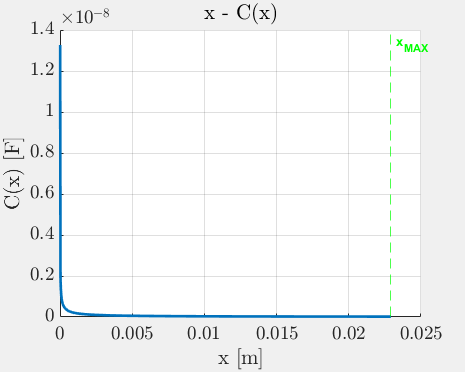

% Plot x - C(x)
myfig(1,"x - C(x)");
hold on
fplot(x, sdata(C(x), 1), [x_min, sdata(x_max)], 'LineWidth', 2)
xline(sdata(x_max), "--g", "x_{MAX}",'LabelOrientation','horizontal', 'FontWeight','bold')
hold off
title("x - C(x)")
xlabel("x [m]")
ylabel("C(x) [F]")

## Max voltage

% Max voltage
% Vmax(x) = A / C * min(epsilon_p * EBD_p, epsilon_f * EBD_f)
Vmax(x) = 2 * t_p / epsilon_p * min(epsilon_p * EBD_p, epsilon_f * EBD_f)

$$Vmax(x) = \frac{2\,{\mathrm{tp}}_{0}\,\left(\epsilon_{3}\left(x\right)+1\right)\,\min\left(\left[{\mathrm{EBD}}_{f}\,\epsilon_{f},{\mathrm{EBD}}_{p}\,\epsilon_{p}\right],\left[\right],2,\text{"omitnan"},{\mathrm{EBD}}_{f}\notin \mathbb{R}\vee {\mathrm{EBD}}_{p}\notin \mathbb{R}\vee \epsilon_{f}\notin \mathbb{R}\vee \epsilon_{p}\notin \mathbb{R}\right)}{\epsilon_{p}}$$

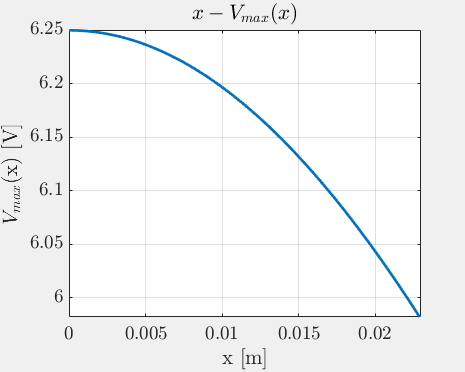


% Plot x - Vmax(x)
myfig(2,"x - Vmax(x)");
fplot(x, sdata(Vmax(x), 1), [x_min, sdata(x_max)], 'LineWidth', 2)
title("$x - V_{max}(x)$")
xlabel("x [m]")
ylabel("$V_{max}$(x) [V]")

## Force

% Force
Uel(x) = 2 * sdata(1 / 2 * (sigma_1 * epsilon_1) * w * t_p * l, 1)

$$Uel(x) = -\frac{15625\,{\left(\sqrt{400\,x^{2}+1}-1\right)}^{2}\,\sqrt{400\,x^{2}+1}\,\left(\frac{3\,\sqrt{400\,x^{2}+1}}{7}-\frac{10}{7}\right)}{91}$$


F(x,V) = simplify(diff(Uel, x) - V^2 / 2 * diff(sdata(C, 1), x), 500)


% Min and max force for V = 0 and V = Vmax
FVmin = vpa(F(x, 0), 4);
FVmax= vpa(F(x, sdata(Vmax, 1)), 4);

% Plot x - F(x)
xtmp = 2e-3:1e-4:2.5e-3;
[~, idx] = min(real(subs(FVmax, x, xtmp)));
xstart = xtmp(idx)

xstart = 0.0020


x_range = x_min:1e-4:sdata(x_max);
FVmin_vec = subs(FVmin,x_range);
FVmax_vec = real(subs(FVmax,x_range));
Uel_Fx = double(trapz(x_range, FVmax_vec) - trapz(x_range, FVmin_vec))

Uel_Fx = 2.4948e-04

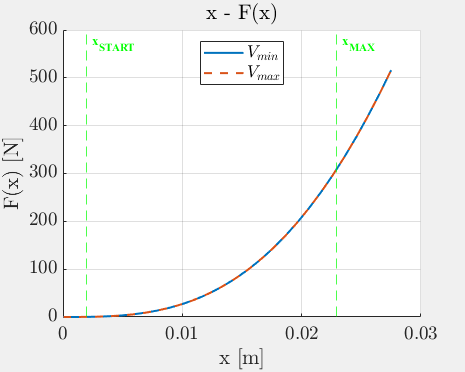


myfig(3,"x - F(x)")
hold on
fplot(x, FVmin, [0, 1.2 * sdata(x_max)], 'LineWidth', 1.5)
fplot(x, FVmax, [0, 1.2 * sdata(x_max)], '--', 'LineWidth', 1.5)
xline(sdata(x_max), "--g", "x_{MAX}",'LabelOrientation','horizontal', 'FontName', 'times new roman', 'FontWeight','bold')
xline(sdata(xstart), "--g", "x_{START}",'LabelOrientation','horizontal', 'FontName', 'times new roman', 'FontWeight','bold')
hold off
legend(["$V_{min}$", "$V_{max}$"], "Location", "north")
title("x - F(x)")
xlabel("x [m]")
ylabel("F(x) [N]")

## Q - V

% Plot Q - V
C_vec = subs(sdata(C, 1), x_range);
Vmax_vec = subs(sdata(Vmax, 1), x_range);
Q_vec = C_vec .* Vmax_vec;

[V_maxstr_min, idx] = min(Q_vec ./ Cmin);
x_min_maxstr = x_range(idx);

[V_minstr_min, idx] = min(Q_vec ./ Cmax);
x_min_minstr = x_range(idx);

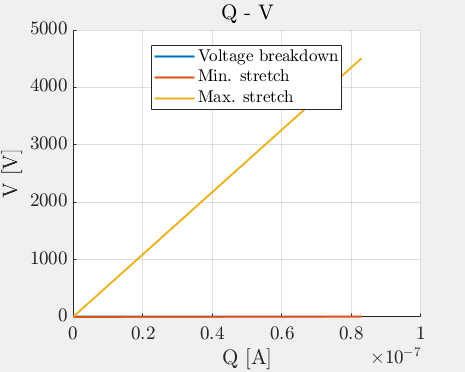

myfig(4,"Q - V"); clf
hold on
plot(Q_vec, Vmax_vec, 'DisplayName', "Voltage breakdown", "LineWidth", 1.5)
plot(Q_vec, Q_vec ./ Cmax, 'DisplayName', "Min. stretch", "LineWidth", 1.5)
plot(Q_vec, Q_vec ./ Cmin, 'DisplayName', "Max. stretch", "LineWidth", 1.5)
legend('Location','best')
xlabel("Q [A]")
ylabel("V [V]")
% ylim([0,max(Vmax_vec)])
title("Q - V")
hold off